% 步骤1: 加载MNIST数据集
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos',...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath,...
    'IncludeSubfolders',true,'LabelSource','foldernames');
disp(imds)

  ImageDatastore - 属性:

                       Files: {
                              ' .../toolbox/nnet/nndemos/nndatasets/DigitDataset/0/image10000.png';
                              ' .../toolbox/nnet/nndemos/nndatasets/DigitDataset/0/image9001.png';
                              ' .../toolbox/nnet/nndemos/nndatasets/DigitDataset/0/image9002.png'
                               ... and 9997 more
                              }
                     Folders: {
                              ' .../MATLAB_R2024a.app/toolbox/nnet/nndemos/nndatasets/DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 9997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage



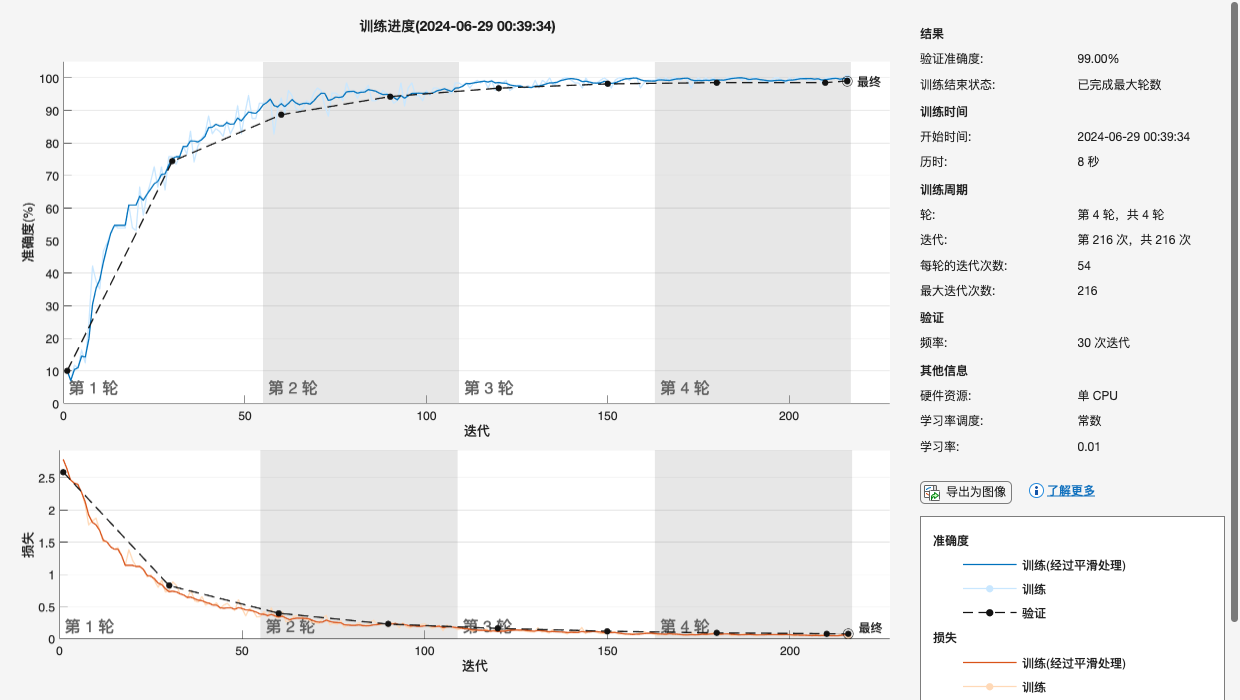

% 步骤2: 划分数据集为训练集和测试集
[imdsTrain,imdsTest] = splitEachLabel(imds,0.7,'randomized');

% 步骤3: 定义CNN网络结构
layers = [
    imageInputLayer([28 28 1])
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

% 步骤4: 配置训练选项
options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsTest, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

% 步骤5: 训练模型
math_ai = trainNetwork(imdsTrain,layers,options);

save('math_ai.mat','math_ai');
% 步骤6: 评估模型
YPred = classify(math_ai,imdsTest);
YTest = imdsTest.Labels;
accuracy = sum(YPred == YTest)/numel(YTest);
disp(['Test Accuracy: ', num2str(accuracy)]);

Test Accuracy: 0.99
